seconds = 10;
dt = .05;
timesteps = seconds/dt;
m = 1;
g = 9.81;

A = [1, 0, 0, dt, 0, 0; 
      0, 1, 0, 0, dt, 0;
      0, 0, 1, 0, 0, dt;
      0, 0, 0, 1, 0, 0;
      0, 0, 0, 0, 1, 0;
      0, 0, 0, 0, 0, 1];
    
B = [0, 0, 0, 0;
     0, 0, 0, 0;
     0, 0, 0, 0;
    dt/m, 0, 0, 0;
    0, dt/m, 0, 0;
    0, 0, dt/m, 0];

X = zeros([timesteps, size(A, 2)]);
X(1, 1) = 5;
X(1, 2) = 10;
X(1, 3) = 20;

c = [0, 0, 0, 0, 0, -g*dt];

%fx, fy, fz, |u|
U = zeros([timesteps-1, size(B, 2)]);

Q = eye(size(A, 2)) *10;
R = eye(size(B, 2));

q = zeros(1, size(A, 2));
r = zeros(1, size(B, 2));

%max angle of x cone
xCon = 30;

uMax = 15;
uMin = 4;

tol = 1e-3;
penalty = .8;
maxDelta = 1;
maxAngle = 5;

tiny = TinyMPC(X, U, A, B, c, Q, R, q, r, xCon, uMax, tol, timesteps, maxAngle, penalty, maxDelta);

tiny = tiny.run();

tiny.U

ans =    -0.5581   -1.1163    2.5209    2.2995
   -0.5588   -1.1176    2.5543    2.3344
   -0.5597   -1.1193    2.5901    2.3718
   -0.5608   -1.1215    2.6286    2.4118
   -0.5621   -1.1242    2.6700    2.4547
   -0.5637   -1.1273    2.7145    2.5008
   -0.5655   -1.1310    2.7625    2.5503
   -0.5677   -1.1353    2.8140    2.6034
   -0.5701   -1.1402    2.8697    2.6606
   -0.5729   -1.1458    2.9296    2.7221


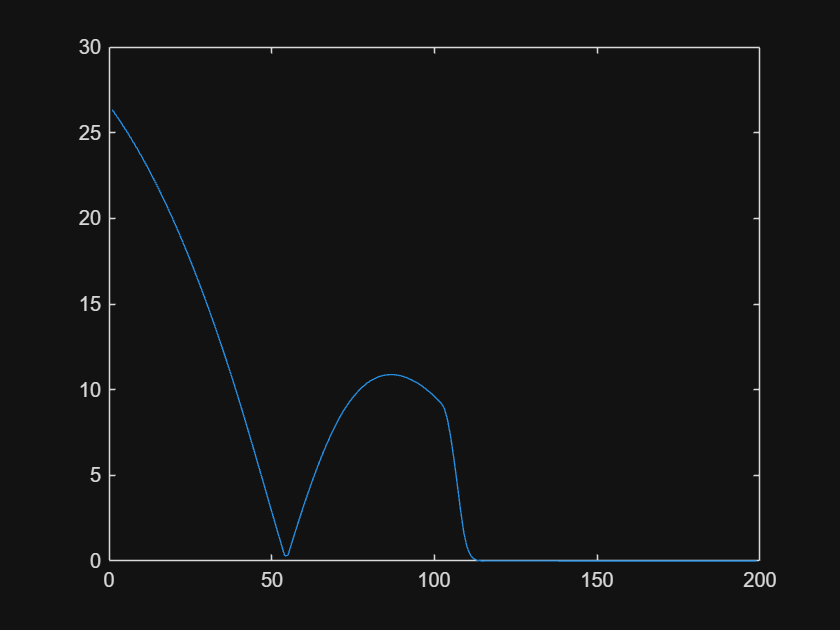

plot(rad2deg(acos(tiny.U(:, 3) ./ vecnorm(squeeze(tiny.U(:, 1:3)), 2, 2))))

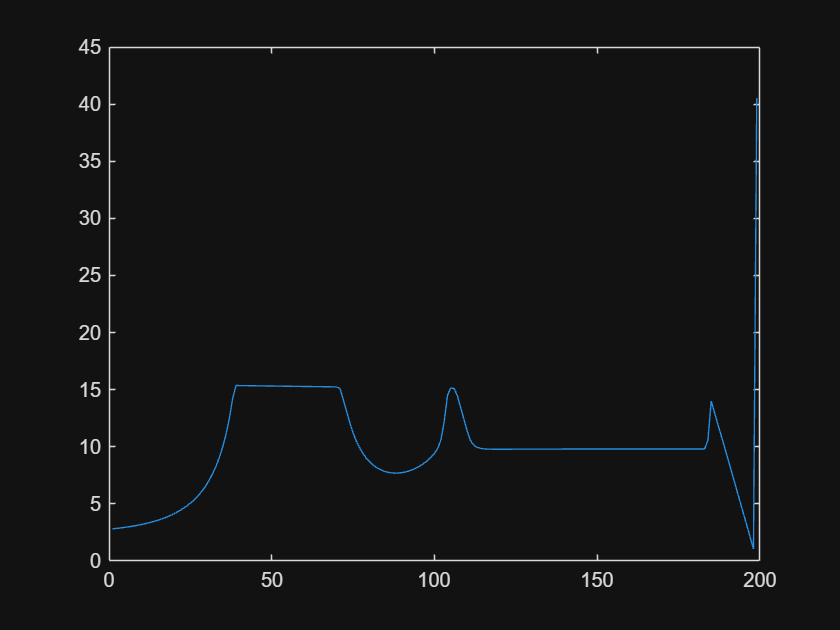

plot(vecnorm(squeeze(tiny.U(:, 1:3)), 2, 2))

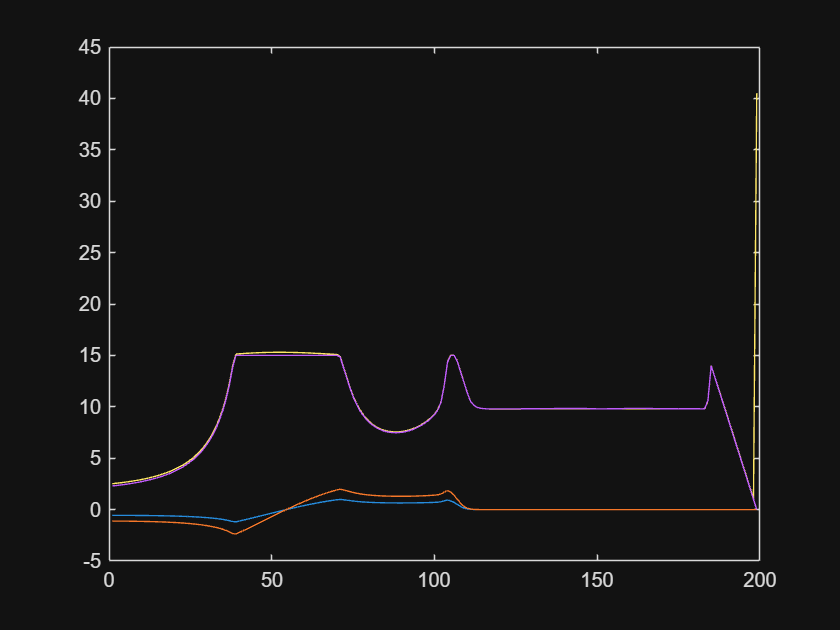

plot(tiny.U)

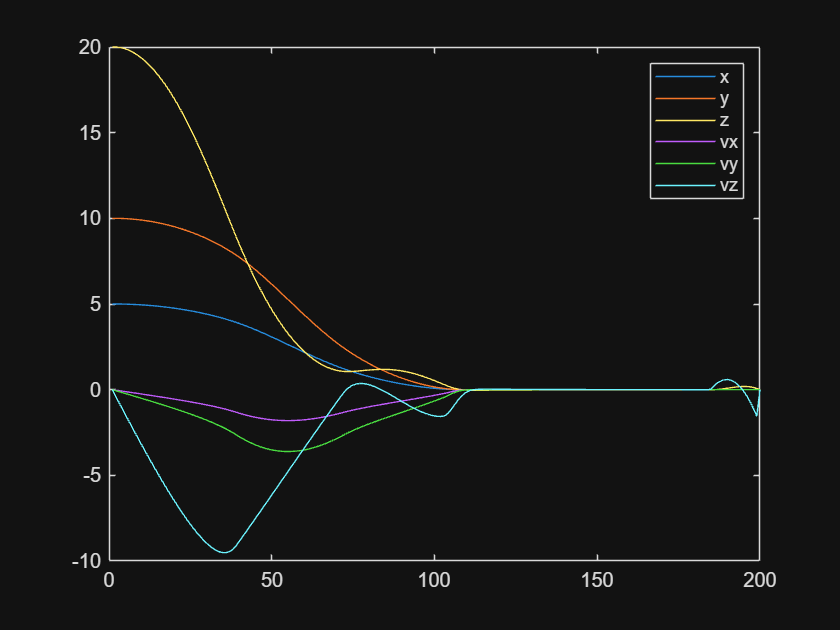

plot(tiny.X)
legend("x", "y", "z", "vx", "vy", "vz")

z_max = max(tiny.X(:, 3));
x_lim = [min(tiny.X(:, 1)) - z_max / 10, max(tiny.X(:, 1)) + z_max / 10];
y_lim = [min(tiny.X(:, 2)) - z_max / 10, max(tiny.X(:, 2)) + z_max / 10];
z_lim = [min(tiny.X(:, 3)) - z_max / 10, z_max * 1.1];

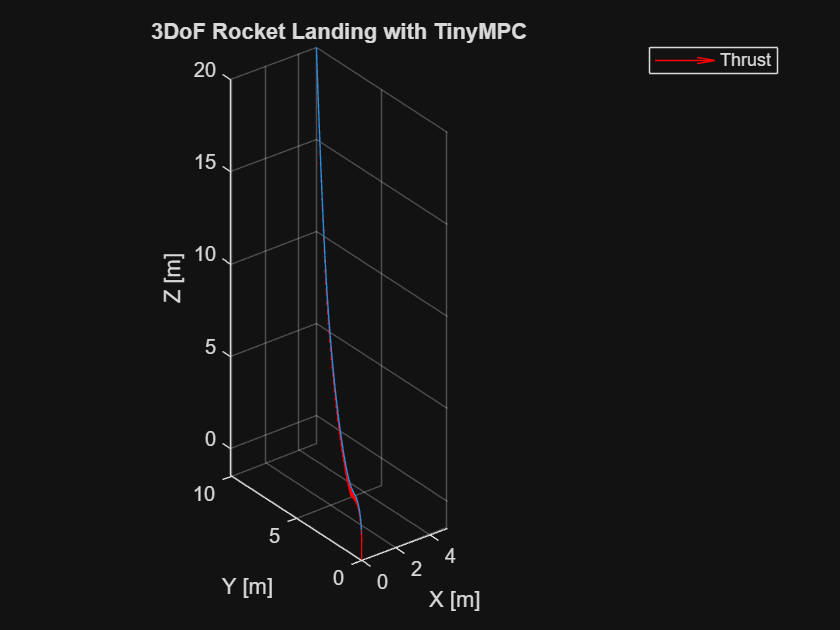


figure
step = 1;
plot3(tiny.X(1:step:end, 1), tiny.X(1:step:end, 2), tiny.X(1:step:end, 3)); hold on
quiver3(tiny.X(2:step:end, 1), tiny.X(2:step:end, 2), tiny.X(2:step:end, 3), -tiny.U(1:step:end, 1), -tiny.U(1:step:end, 2), -tiny.U(1:step:end, 3), ShowArrowHead = "off", color = "r")
title("3DoF Rocket Landing with TinyMPC")
legend("", "Thrust")
xlabel("X [m]")
ylabel("Y [m]")
zlabel("Z [m]")
xlim(x_lim)
ylim(y_lim)
zlim(z_lim)
axis equal
grid on
hold off

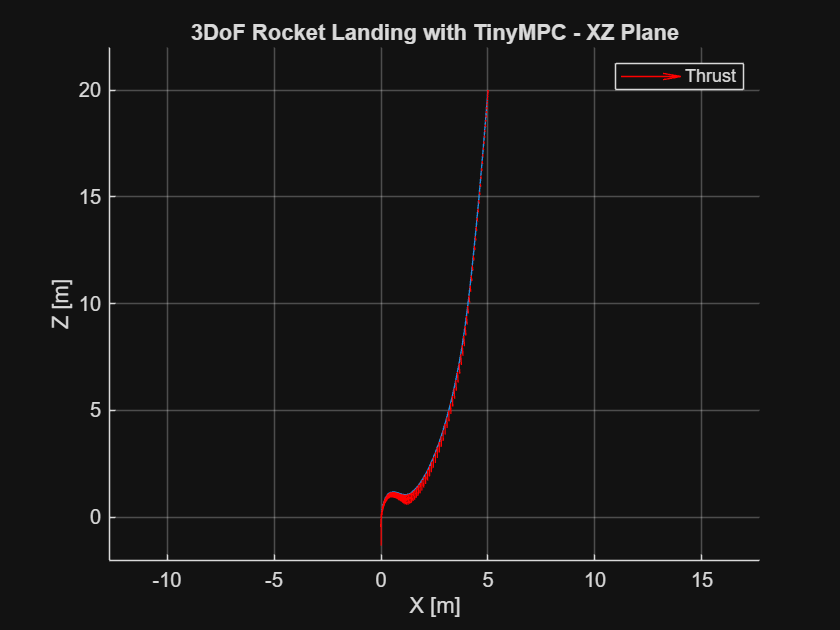

figure
hold on
plot(tiny.X(1:step:end, 1), tiny.X(1:step:end, 3)); hold on
quiver(tiny.X(2:step:end, 1), tiny.X(2:step:end, 3), -tiny.U(1:step:end, 1), -tiny.U(1:step:end, 3), ShowArrowHead = "off", color = "r")
title("3DoF Rocket Landing with TinyMPC - XZ Plane")
legend("", "Thrust")
xlabel("X [m]")
ylabel("Z [m]")
xlim(x_lim)
ylim(z_lim)
axis equal
grid on
hold off

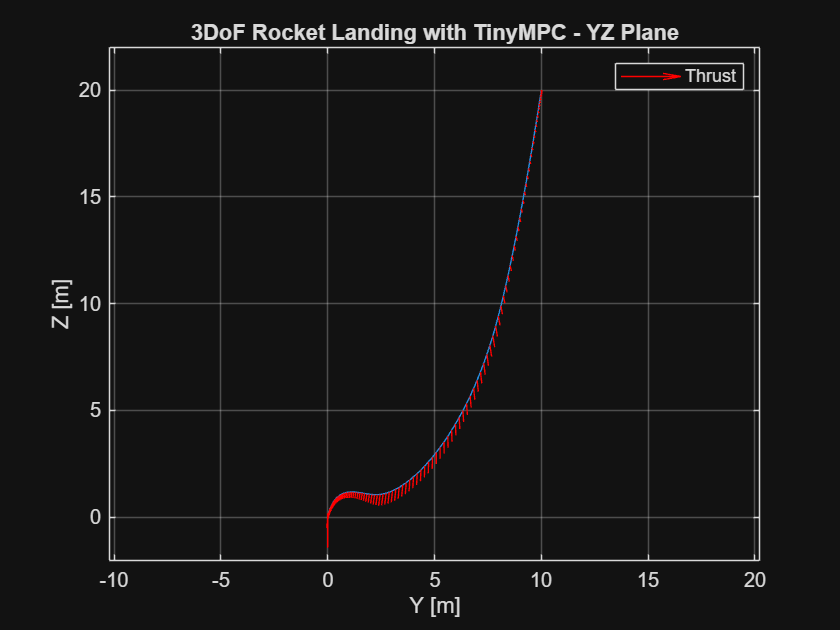

figure
plot(tiny.X(1:step:end, 2), tiny.X(1:step:end, 3)); hold on
quiver(tiny.X(2:step:end, 2), tiny.X(2:step:end, 3), -tiny.U(1:step:end, 2), -tiny.U(1:step:end, 3), ShowArrowHead = "off", color = "r")
title("3DoF Rocket Landing with TinyMPC - YZ Plane")
legend("", "Thrust")
xlabel("Y [m]")
ylabel("Z [m]")
xlim(y_lim)
ylim(z_lim)
axis equal
grid on
hold off